% =========================================================================
% SIM_08: Nonlinear Reconfiguration with Optimized Delta-V and Thrust Profiles
% =========================================================================

clear; clc; close all;

%% --- PARAMETERS ---
N = 4;
dt = 10;
K = 40;                             % Longer time horizon
T = K * dt;
mass = 10;
umax = 0.05;
d_min = 10;                         % Reduced to improve ∆V
nx = 4; nu = 2;

%% --- INITIAL & FINAL STATES ---
x0 = [  0   0   0   0;
       10   0   0   0;
        0  10   0   0;
      -10   0   0   0];

xf = [  0  10   0   0;
       10  10   0   0;
        0 -10   0   0;
      -10 -10   0   0];

%% --- INITIAL GUESS ---
z0 = zeros(N*K*nu + N*(K+1)*nx, 1);
for i = 1:N
    for k = 1:K+1
        alpha = (k-1)/K;
        xi = (1-alpha)*x0(i,:) + alpha*xf(i,:);
        idx = N*K*nu + (i-1)*(K+1)*nx + (k-1)*nx + (1:nx);
        z0(idx) = xi';
    end
end

%% --- BOUNDS ---
u_lb = -umax * ones(N*K*nu, 1);
u_ub =  umax * ones(N*K*nu, 1);
x_bounds = 1e3;
x_lb = -x_bounds * ones(N*(K+1)*nx, 1);
x_ub =  x_bounds * ones(N*(K+1)*nx, 1);
lb = [u_lb; x_lb];
ub = [u_ub; x_ub];

%% --- OBJECTIVE FUNCTION ---
objective = @(z) cost_with_collision_penalty(z, N, K, nu, nx, d_min);

%% --- NONLINEAR CONSTRAINTS ---
nonlcon = @(z) nonlinear_constraints(z, x0, xf, N, K, dt, nu, nx);

%% --- OPTIMIZATION OPTIONS ---
options = optimoptions('fmincon', ...
    'Display', 'iter', ...
    'MaxIterations', 250, ...
    'MaxFunctionEvaluations', 5e4, ...
    'StepTolerance', 1e-4, ...
    'ConstraintTolerance', 1e-3, ...
    'OptimalityTolerance', 1e-3, ...
    'Algorithm', 'sqp');

[z_opt, fval] = fmincon(objective, z0, [], [], [], [], lb, ub, nonlcon, options);

 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0         977    8.880625e+05     5.000e-01     1.000e+00     0.000e+00     1.950e+04  
    1        1954    2.009904e+04     2.557e-06     1.000e+00     2.325e+03     1.974e+04  
    2        2932    1.468871e+04     1.166e-06     7.000e-01     3.074e+02     8.462e+03  
    3        3909    4.554820e+00     9.069e-03     1.000e+00     4.671e+02     1.819e+04  
    4        4886    4.527240e+00     6.081e-08     1.000e+00     1.131e+01     3.595e+01  
    5        5863    4.438252e+00     5.502e-10     1.000e+00     3.133e-01     1.936e+00  
    6        6842    4.409965e+00     2.049e-09     4.900e-01     8.560e-01     1.983e+00  
    7        7819    4.322722e+00     4.598e-10     1.000e+00     3.759e-01     1.231e+00  
    8        8798    4.316327e+00     3.030e-10     4.900e-01     1.342e-01     1.

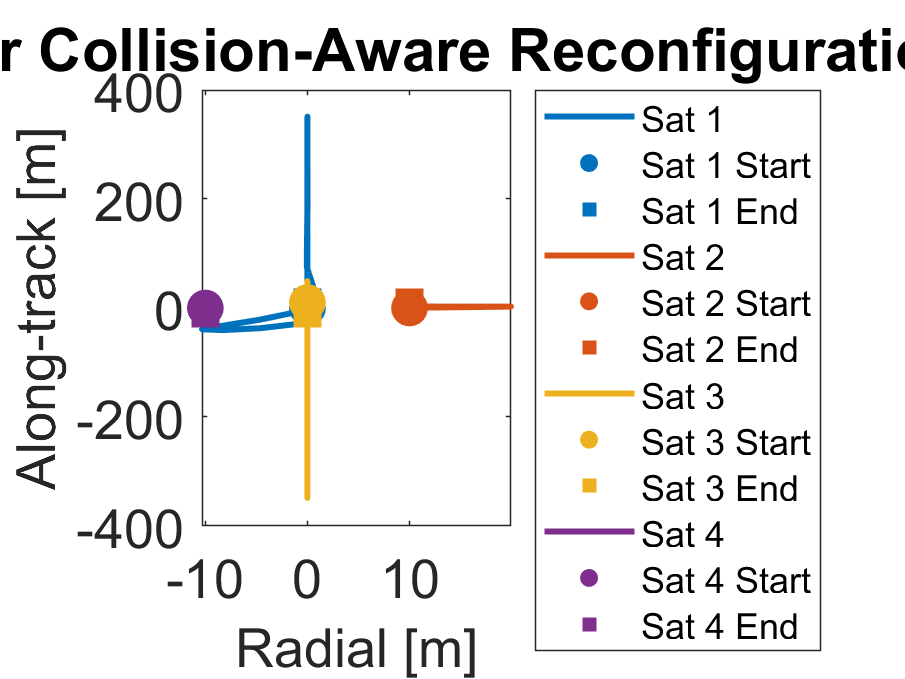


%% --- EXTRACT RESULTS ---
U = reshape(z_opt(1:N*K*nu), [nu, K, N]);
X = zeros(nx, K+1, N);
for i = 1:N
    base = N*K*nu + (i-1)*(K+1)*nx;
    for k = 1:K+1
        idx = base + (k-1)*nx + (1:nx);
        X(:,k,i) = z_opt(idx);
    end
end

%% --- TRAJECTORY PLOT WITH CUSTOM LEGEND ---
figure; hold on; %grid on;
box on;
set(gca, 'FontSize', 18)

colors = lines(N);
legendHandles = [];
legendEntries = [];

for i = 1:N
    traj = squeeze(X(1:2,:,i))';
    
    % Plot path
    h = plot(traj(:,1), traj(:,2), 'Color', colors(i,:), 'LineWidth', 2);
    legendHandles(end+1) = h;
    legendEntries{end+1} = sprintf('Sat %d', i);
    
    % Start marker
    hStart = scatter(traj(1,1), traj(1,2), 150, colors(i,:), 'filled', 'o');
    legendHandles(end+1) = hStart;
    legendEntries{end+1} = sprintf('Sat %d Start', i);
    
    % End marker
    hEnd = scatter(traj(end,1), traj(end,2), 150, colors(i,:), 'filled', 's');
    legendHandles(end+1) = hEnd;
    legendEntries{end+1} = sprintf('Sat %d End', i);
end

legend(legendHandles, legendEntries, 'Location', 'bestoutside', 'FontSize', 12);
xlabel('Radial [m]', 'FontSize', 18);
ylabel('Along-track [m]', 'FontSize', 18);
title('Nonlinear Collision-Aware Reconfiguration', 'FontSize', 20);
set(gcf, 'Units', 'inches', 'Position', [1, 1, 8, 6]);
exportgraphics(gcf, 'SIM_08_trajectory2.png', 'Resolution', 300);


%% --- DELTA-V REPORT ---
disp("Total Delta-V per satellite [m/s]:");

Total Delta-V per satellite [m/s]:


for i = 1:N
    acc = squeeze(U(:,:,i));
    deltaV(i,1) = sum(vecnorm(acc, 2, 1)) * dt;
end
disp(deltaV);

   19.0902
    1.3052
   18.6599
    0.1698




%% --- FINAL POSITION ERROR ---
disp("Final Position Errors [m]:");

Final Position Errors [m]:


for i = 1:N
    err = norm(X(1:2,end,i) - xf(i,1:2)');
    fprintf("Satellite %d: %.4f m\n", i, err);
end

Satellite 1: 0.0000 m
Satellite 2: 0.0000 m
Satellite 3: 0.0000 m
Satellite 4: 0.0000 m


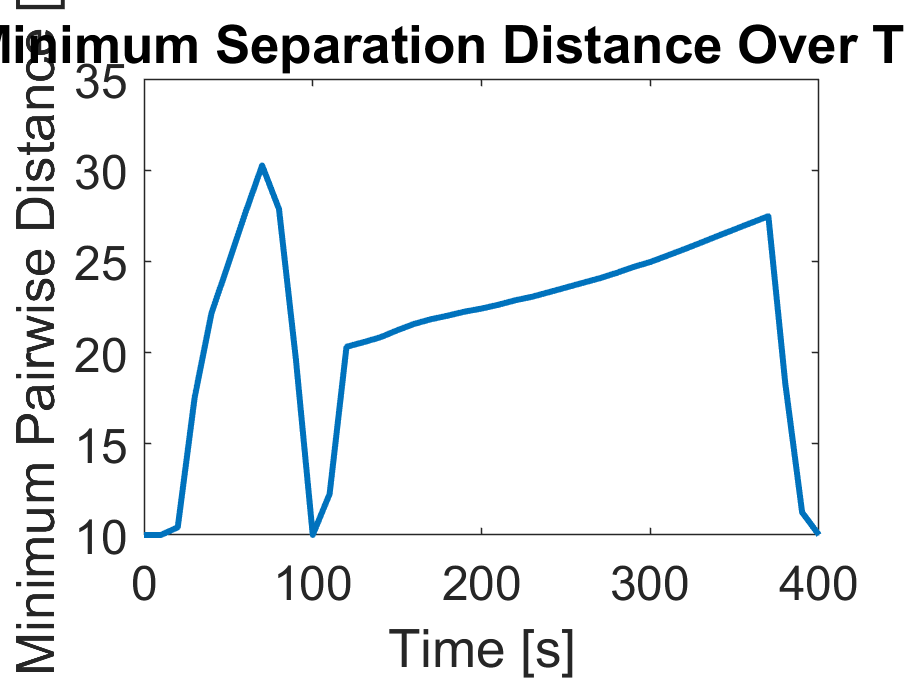


%% --- MINIMUM SEPARATION PLOT ---
min_sep = zeros(K+1, 1);
for k = 1:K+1
    dists = [];
    for i = 1:N-1
        for j = i+1:N
            d = norm(X(1:2,k,i) - X(1:2,k,j));
            dists(end+1) = d;
        end
    end
    min_sep(k) = min(dists);
end

figure; plot((0:K)*dt, min_sep, 'LineWidth', 2);
xlabel('Time [s]', 'FontSize', 18);
ylabel('Minimum Pairwise Distance [m]', 'FontSize', 18);
title('Minimum Separation Distance Over Time', 'FontSize', 20);
%grid on; 
box on;
set(gca, 'FontSize', 16);

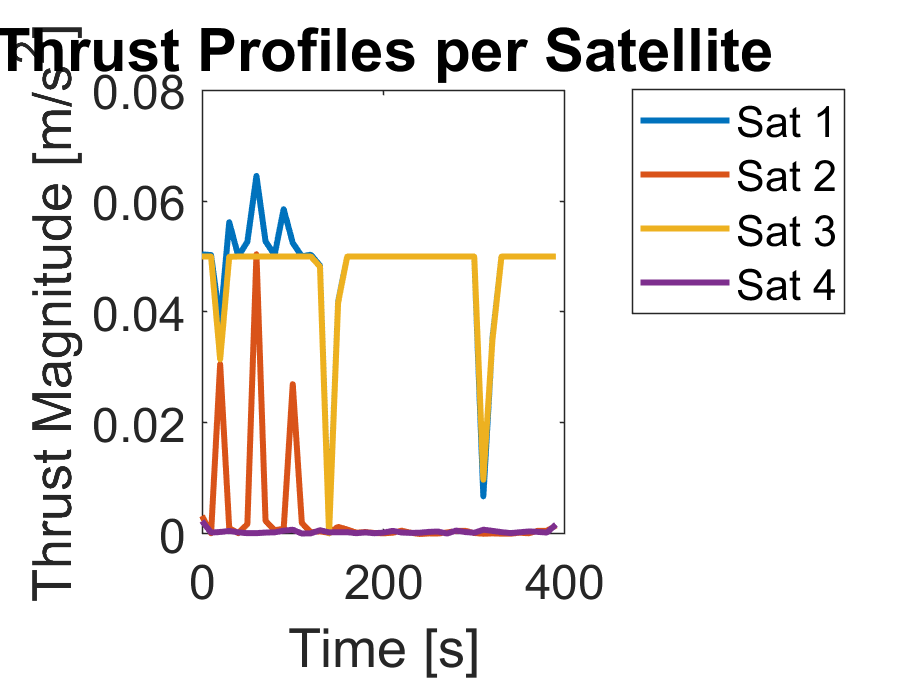


%% --- THRUST MAGNITUDE PROFILES ---
figure; hold on; %grid on;
box on;
set(gca, 'FontSize', 16)
time = (0:K-1) * dt;

for i = 1:N
    acc = squeeze(U(:,:,i));
    thrust_mag = vecnorm(acc, 2, 1);
    plot(time, thrust_mag, 'LineWidth', 2);
end

xlabel('Time [s]', 'FontSize', 18);
ylabel('Thrust Magnitude [m/s^2]', 'FontSize', 18);
title('Thrust Profiles per Satellite', 'FontSize', 20);
legend("Sat 1", "Sat 2", "Sat 3", "Sat 4", 'Location', 'northeastoutside');
set(gcf, 'Units', 'inches', 'Position', [1, 1, 8, 6]);
exportgraphics(gcf, 'SIM_08_thrust.png', 'Resolution', 300);


%% ================== FUNCTIONS AT END ==================


function J = cost_with_collision_penalty(z, N, K, nu, nx, d_min)
    U = reshape(z(1:N*K*nu), [nu, K, N]);
    X = zeros(2, K+1, N);
    for i = 1:N
        base = N*K*nu + (i-1)*(K+1)*nx;
        for k = 1:K+1
            idx = base + (k-1)*nx + (1:2);
            X(:,k,i) = z(idx);
        end
    end
    thrust_cost = sum(vecnorm(reshape(U, [nu, K*N]), 2, 1));
    penalty = 0;
    for k = 1:K+1
        for i = 1:N-1
            for j = i+1:N
                dij = norm(X(:,k,i) - X(:,k,j));
                if dij < d_min
                    penalty = penalty + 1e3 * (d_min - dij)^2;
                end
            end
        end
    end
    J = thrust_cost + penalty;
end

function [c, ceq] = nonlinear_constraints(z, x0, xf, N, K, dt, nu, nx)
    U = reshape(z(1:N*K*nu), [nu, K, N]);
    X = zeros(nx, K+1, N);
    for i = 1:N
        base = N*K*nu + (i-1)*(K+1)*nx;
        for k = 1:K+1
            idx = base + (k-1)*nx + (1:nx);
            X(:,k,i) = z(idx);
        end
    end
    ceq = [];
    for i = 1:N
        ceq = [ceq; X(:,1,i) - x0(i,:)'];
        for k = 1:K
            pos_next = X(1:2,k,i) + dt * X(3:4,k,i);
            vel_next = X(3:4,k,i) + dt * U(:,k,i);
            ceq = [ceq;
                   X(1:2,k+1,i) - pos_next;
                   X(3:4,k+1,i) - vel_next];
        end
        ceq = [ceq; X(:,end,i) - xf(i,:)'];
    end
    c = [];  % No hard inequality constraints
end
